# Interactive ICS GUI

Load Data Stack

[fileID, filePath] = uigetfile("*.tif");
stack = readFileToStack([filePath, fileID]);

Load Vector Field if available:

[VMfile, VMpath] = uigetfile("*.mat");
load([VMpath, VMfile]);

## ICS Explorer GUI

### Design

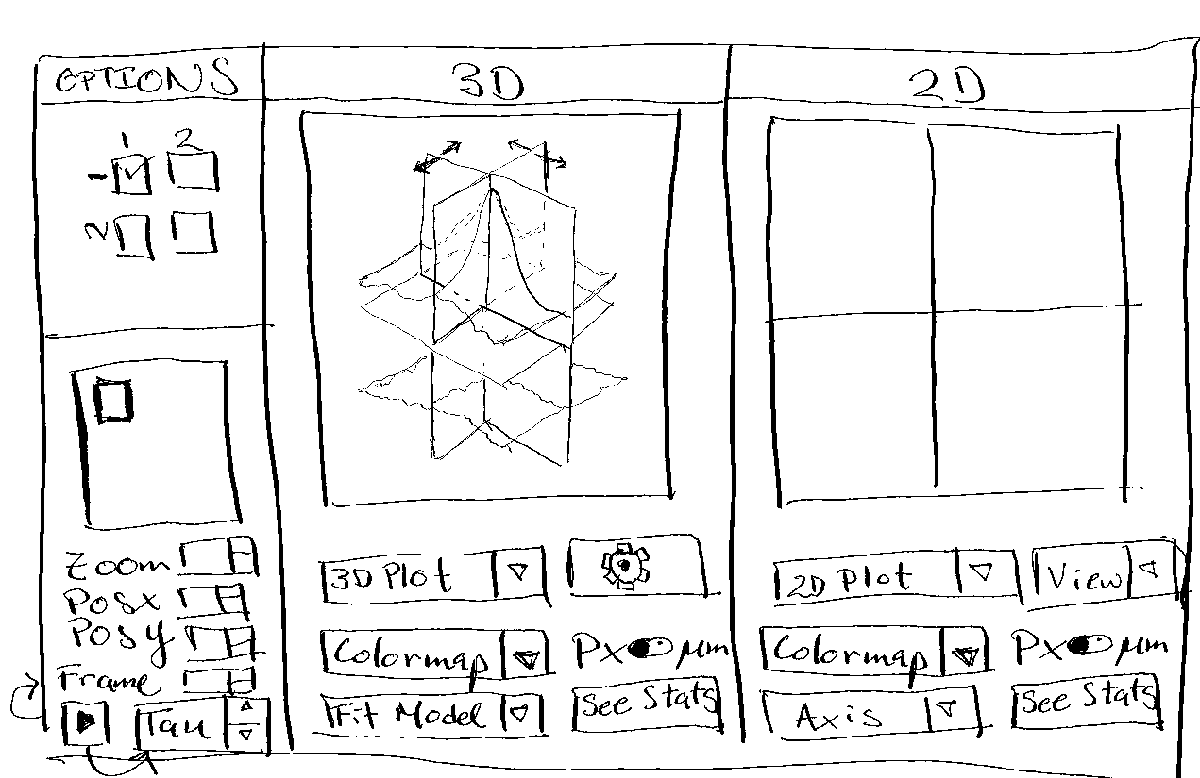

### Navigator

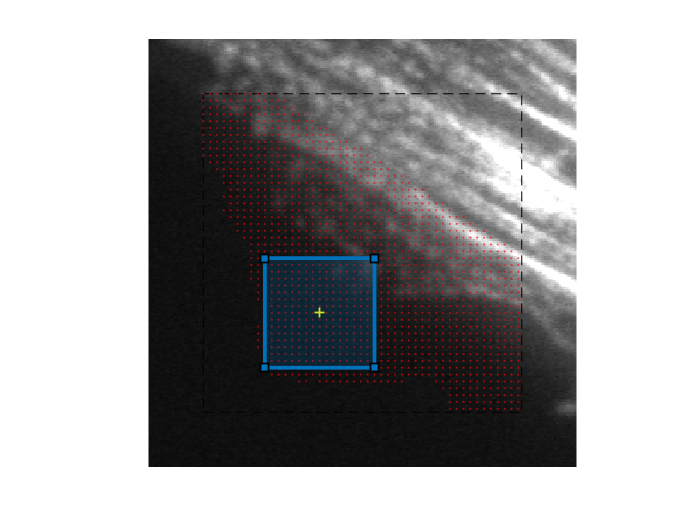

ans =    68.5000  128.5000   64.0000   64.0000


figure;
minframe = floor(opt.TOIsize/2) + mod(opt.TOIsize,2);
maxframe = size(stack, 3) - floor(opt.TOIsize/2);
frame = 5;
if mod(opt.TOIsize,2) == 0 % TOI size is even
    minK = 1;
else 
    minK = 0; % TOI size is odd
end
k = frame - floor(opt.TOIsize/2) + minK; % Vector field frame
imshow(stack(:,:,frame), [100,1000], "InitialMagnification","fit"); axis image; hold on

vix = 33; % Vector index in x
viy = 18; % Vector index in y

px = position_x(vix,1); %(vix-1)*opt.ROIshift + opt.ROIshift + 1/2; % Vector position in x (in pixels)
py = position_y(1,viy); %(viy-1)*opt.ROIshift + opt.ROIshift + 1/2; % Vector position in y (in pixels)

if minframe <= frame && frame <= maxframe
    rectangle('Position', [(1+opt.ROIsize)/2 (1+opt.ROIsize)/2 size(stack,1)-opt.ROIsize size(stack,1)-opt.ROIsize], 'FaceColor','none', 'LineStyle','--'); hold on
    rectangle('Position', [py-opt.ROIsize/2 px-opt.ROIsize/2 opt.ROIsize opt.ROIsize]);
    roi = drawrectangle("Position", [py-opt.ROIsize/2 px-opt.ROIsize/2 opt.ROIsize opt.ROIsize],...
        "AspectRatio",1,"FixedAspectRatio",true,"InteractionsAllowed","translate");
    roi.Position
    maskedPosX = position_x.* opt.vectorPositions;
    maskedPosX(maskedPosX == 0) = NaN;
    maskedPosY = position_y.* opt.vectorPositions;
    maskedPosY(maskedPosY == 0) = NaN;
    plot(maskedPosY, maskedPosX, '.r', 'MarkerSize', 2);
    plot(py, px,'+y', 'LineWidth', 1);
end

roi.Position;

### 3D ICF plot

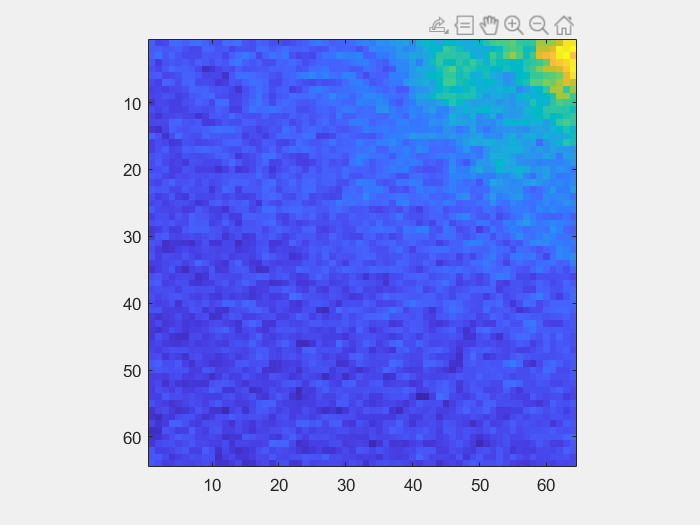

fracROIshift = opt.ROIsize/opt.ROIshift;
fracTOIshift = opt.TOIsize/opt.TOIshift;
TOIFOV = stack(floor(1+(vix-1)/fracROIshift*opt.ROIsize):floor(opt.ROIsize*(1+((vix-1)/fracROIshift))),...
    floor(1+(viy-1)/fracROIshift*opt.ROIsize):floor(opt.ROIsize*(1+((viy-1)/fracROIshift))),...
    floor(1+(k-1)/fracTOIshift*opt.TOIsize):floor(opt.TOIsize*(1+((k-1)/fracTOIshift))));
h = figure;
% imagesc(TOIFOV(:,:,1)); axis image
M(size(TOIFOV,3)) = struct('cdata', [], 'colormap', []);
h.Visible = 'off';
for m = 1:size(TOIFOV,3)
    imagesc(TOIFOV(:,:,m)); axis image
    drawnow
    M(m) = getframe;
end
h.Visible = 'on';

% movie(M,1,1);
% implay(M,3);

[corrfn] = stics(TOIFOV, opt.tauLimit);

fitMode = "rotated";



[coeffGfit] = gaussfit(corrfn,fitMode,opt.pixelSize,'n',opt.fitRadius);

maxTau = min(opt.tauLimit, size(coeffGfit,1))-1;
tau = 1;

G = coeffGfit(tau + 1,:)

G =     0.0165    1.1144    0.7519         0    0.0346    0.0833    0.0237    0.0326


[meshX,meshY] = meshgrid(-((size(corrfn,2)-1)/2)*opt.pixelSize:opt.pixelSize:((size(corrfn,2)-1)/2)*opt.pixelSize,...
    -((size(corrfn,1)-1)/2)*opt.pixelSize:opt.pixelSize:((size(corrfn,1)-1)/2)*opt.pixelSize);
% High Resolution Grid
h=3; % Resolution factor
[xh,yh] = meshgrid(-opt.ROIsize/2:opt.pixelSize/h:opt.ROIsize/2,...
    -opt.ROIsize/2:1/h:opt.ROIsize/2);


switch fitMode
    case "time"
        A = G(1);
        Sx = G(2);
        Sy = G(3);
        Offset = G(4);
        X_0 = G(5);
        Y_0 = G(6);
        Z = A.*exp(-(((meshX-X_0).^2)/(2*Sx.^2) + ((meshY-Y_0).^2)/(2*Sy.^2))) + Offset;
        
%         coeffGfit(:,7) = zeros(size(coeffGfit,1),1);
        G(7) = 0;
        

### Isotropic model ($\sigma_{x} = \sigma_{y}$) 


$$f(x,y)=a\cdot \exp \left ( -\left (\frac{(x-x_{0})^2}{2\sigma^2_{X}} + \frac{(y-y_{0})^2}{2\sigma_{Y}^2} \right )\right )$$


    case "timeasym"
        A = G(1);
        Sx = G(2);
        Sy = G(3);
        Offset = G(4);
        X_0 = G(5);
        Y_0 = G(6);
        Z = A.*exp(-(((meshX-X_0).^2)/(2*Sx.^2) + ((meshY-Y_0).^2)/(2*Sy.^2))) + Offset;
        
%         coeffGfit(:,7) = zeros(size(coeffGfit,1),1);
        G(7) = 0;

### Asymetric model ($\sigma_{x} \neq \sigma_{y}$) 


$$f(x,y)=a\cdot \exp \left ( -\left (\frac{(x-x_{0})^2}{2\sigma^2_{X}} + \frac{(y-y_{0})^2}{2\sigma_{Y}^2} \right )\right )$$


    case "rotated"
        A = G(1);
        Sx = G(2);
        Sy = G(3);
        X_0 = G(5);
        Y_0 = G(6);        
        Z = A*exp( -(...
            ( meshX*cos(G(7))-meshY*sin(G(7)) - X_0*cos(G(7)) + Y_0*sin(G(7)) ).^2/(2*Sx^2) + ... 
            ( meshX*sin(G(7))+meshY*cos(G(7)) - X_0*sin(G(7)) - Y_0*cos(G(7)) ).^2/(2*Sy^2) ) );

### Rotated model ($\theta \neq 0$) 


$$f(x,y)=a\cdot \exp \left ( -\left (\frac{(x \cos \theta - y \sin \theta - x_{0} \cos \theta + y_{0} \sin \theta) ^2}{2\sigma^2_{X}} + \frac{(x \sin \theta + y \cos \theta - x_{0} \sin \theta - y_{0} \cos \theta )^2}{2\sigma_{Y}^2} \right )\right )$$


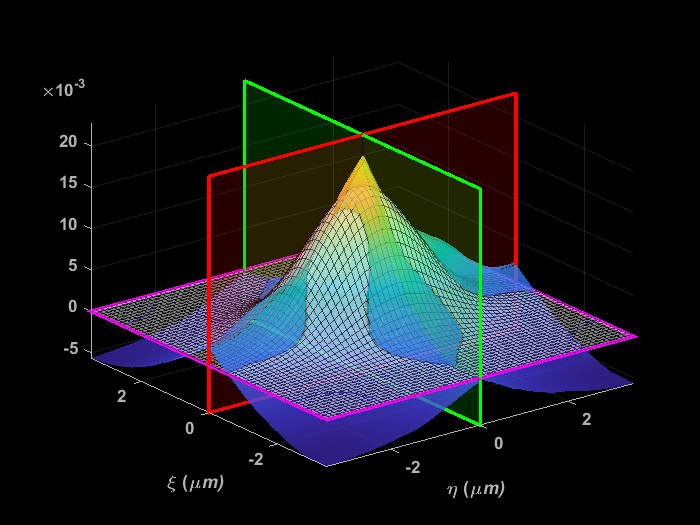

end

xPanPos = 0; yPanPos = 0; zPanPos = 0;

ICS3Dplot = figure;
s = surf(meshX, meshY, corrfn(:,:,tau+1)); axis tight
s.EdgeColor = 'none';
s.FaceAlpha = 0.75;
shading interp
hold on;

m = mesh(meshX, meshY, Z);
m.EdgeColor = [0 0 0];
m.EdgeAlpha = 0.5;
m.FaceAlpha = 0.5;

c = contour(meshX, meshY, corrfn(:,:,tau+1));

xPan = fill3([xPanPos;xPanPos;xPanPos;xPanPos],...
            [meshY(1,1);meshY(1,1);meshY(end,1);meshY(end,1)],...
            [min(corrfn(:,:,1),[],'all');max(corrfn(:,:,1),[],'all');max(corrfn(:,:,1),[],'all');min(corrfn(:,:,1),[],'all')],'g');
xPan.FaceAlpha = 0.15;
xPan.EdgeColor = 'g'; 
xPan.LineWidth = 2;

yPan = fill3([meshX(1,1);meshX(1,1);meshX(1,end);meshX(1,end)],...
            [yPanPos;yPanPos;yPanPos;yPanPos],...
            [min(corrfn(:,:,1),[],'all');max(corrfn(:,:,1),[],'all');max(corrfn(:,:,1),[],'all');min(corrfn(:,:,1),[],'all')],'r');
yPan.FaceAlpha = 0.15;
yPan.EdgeColor = 'r'; 
yPan.LineWidth = 2;

zPan = fill3([meshX(1,1);meshX(1,1);meshX(1,end);meshX(1,end)],...
            [meshY(1,1);meshY(end,1);meshY(end,1);meshY(1,1)],...
            [zPanPos;zPanPos;zPanPos;zPanPos],'m');
zPan.FaceAlpha = 0;
zPan.EdgeColor = 'm'; 
zPan.LineWidth = 2;


hold off;
xlabel('\eta (\mu\itm)');
ylabel('\xi (\mu\itm)');
ICS3Dplot.Color = 'k';
ICS3Daxis = gca;
% ICS3Daxis.XColor
set(gca,'XColor',[0.7 0.7 0.7],'YColor',[0.7 0.7 0.7],'ZColor',[0.7 0.7 0.7]);
set(gca,'Color','none','FontWeight','bold');

clf

## 2D Plot

### ICF

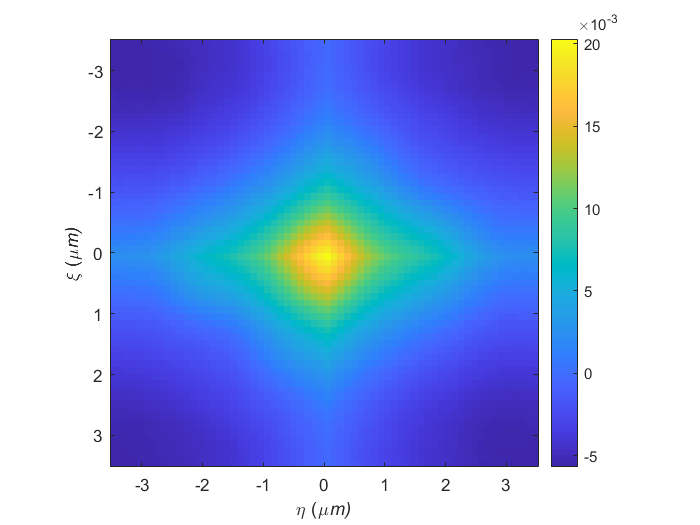

figure;
imagesc(meshX(1,:), meshY(:,1), corrfn(:,:,tau+1)); axis square; colorbar;
hold on;
plot(G(5), G(6), "+r","LineWidth",1.5);
xlabel('\eta (\mu\itm)');
ylabel('\xi (\mu\itm)');

### Fit

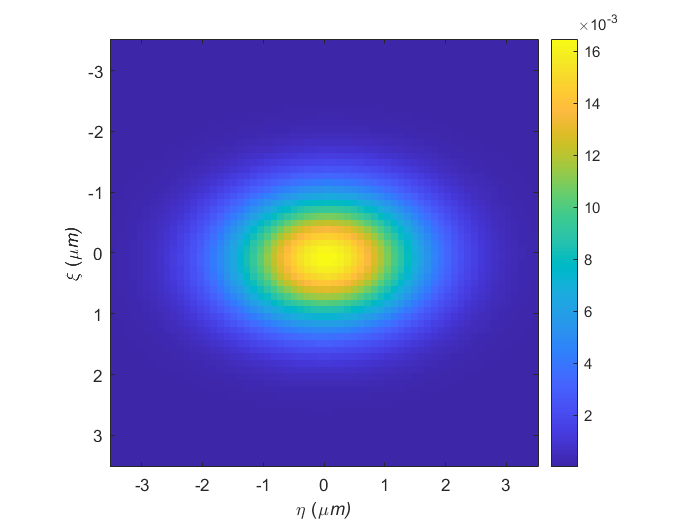

figure;
imagesc(meshX(1,:), meshY(:,1), Z); axis square; colorbar;
xlabel('\eta (\mu\itm)');
ylabel('\xi (\mu\itm)');

### Residuals

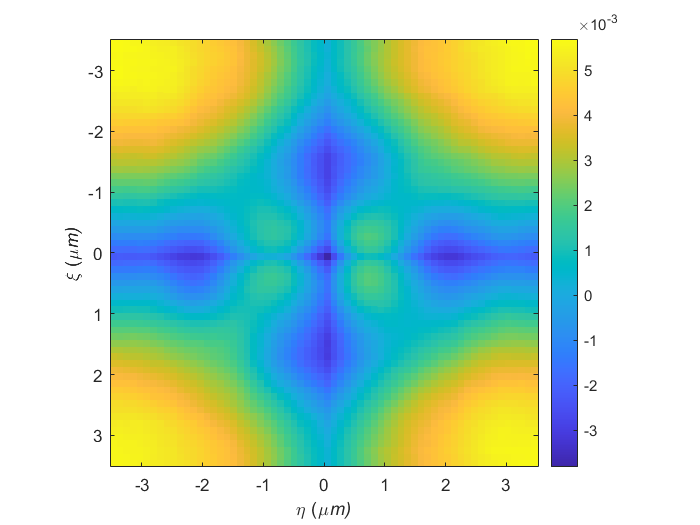

if strcmp(fitMode,"rotated")
    figure;
    imagesc(meshX(1,:), meshY(:,1), residuals(:,:,tau+1)); axis square; colorbar;
    xlabel('\eta (\mu\itm)');
    ylabel('\xi (\mu\itm)');
else
    disp('Residuals plot currently not available when using Isotropic or Asymetric Models');
end

### Axis Cross-Sections

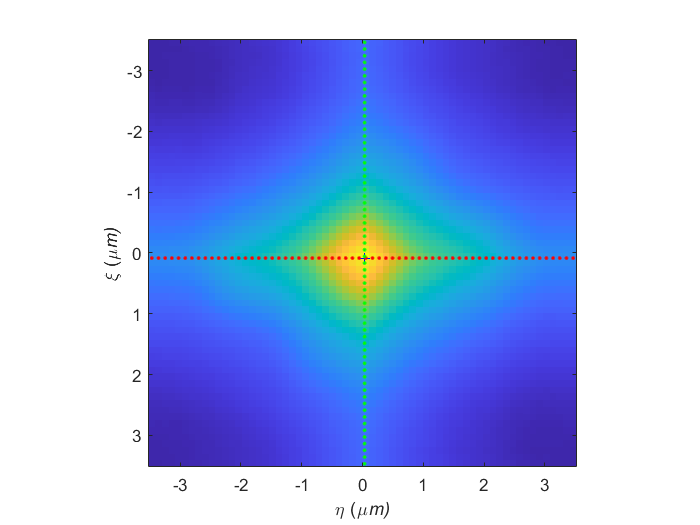

figure;
imagesc(meshX(1,:), meshY(:,1), corrfn(:,:,tau+1)); axis square;
xlabel('\eta (\mu\itm)');
ylabel('\xi (\mu\itm)');

% % Output and compare data and fitted function coefs
% text(-n/2-5,m/2+5.0,sprintf('\t Amplitude \t X-Coord \t X-Width \t Y-Coord \t Y-Width \t Angle'),'Color','black');
% text(-n/2-5,m/2+6.2,sprintf('Set \t %1.3f \t %1.3f \t %1.3f \t %1.3f \t %1.3f \t %1.3f',A_s),'Color','blue');
% text(-n/2-5,m/2+7.4,sprintf('Fit \t %1.3f \t %1.3f \t %1.3f \t %1.3f \t %1.3f \t %1.3f',A),'Color','red');

% Plot vertical and horizontal axis
vx_h=meshX(1,:); vy_v=meshY(:,1); PanMin = vx_h(1,1); PanMax = vx_h(1,end);PixelSize = opt.pixelSize;
InterpMethod='nearest'; % 'nearest','linear','spline','cubic'
AxisView = "XY axis";
CenteredPannels = 1;
switch AxisView
    case "XY axis"
        % generate points along horizontal & vertical axis
        if ~CenteredPannels
            xPanPos = -0.935;
            yPanPos = 0;
        end
        vy_h=(G(6)+yPanPos)*ones(size(vx_h)); hPoints = interp2(meshX,meshY,corrfn(:,:,tau+1),vx_h,vy_h,InterpMethod);
        vx_v=(G(5)+xPanPos)*ones(size(vy_v)); vPoints = interp2(meshX,meshY,corrfn(:,:,tau+1),vx_v,vy_v,InterpMethod);
    case "Z axis"
    case "Major Minor axis", M = -tan(G(7));
        % generate points along Major & Minor axis
        vy_h=M*(vx_h-G(5))+G(6)+yPanPos; hPoints = interp2(meshX,meshY,corrfn(:,:,tau+1),vx_h,vy_h,InterpMethod);
        vx_v=M*(G(6)-vy_v)+G(5)-xPanPos; vPoints = interp2(meshX,meshY,corrfn(:,:,tau+1),vx_v,vy_v,InterpMethod);
end

% plot lines 
hold on; plot(G(5),G(6),'+b',vx_h,vy_h,'.r',vx_v,vy_v,'.g'); hold off;

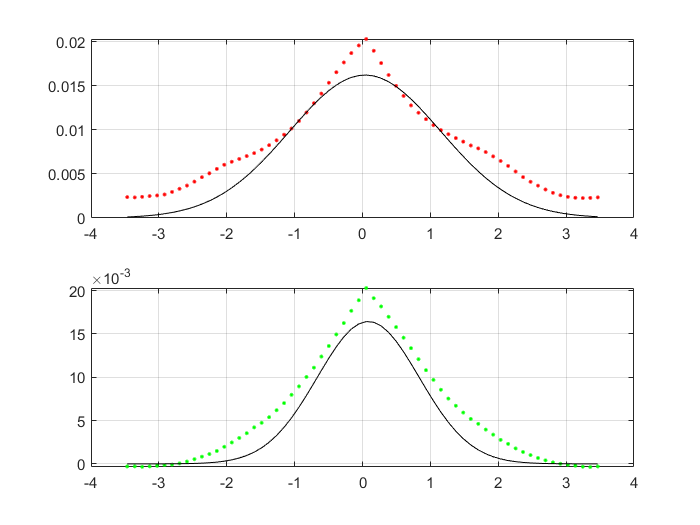


% Plot cross sections 
dmin=1.1*min(corrfn(:,:,tau+1),[], 'all'); 
% xfit=xh(1,:)*opt.pixelSize; hfit = G(1)*exp(-(xfit-G(5)).^2/(2*G(2)^2));
% %High resolution version, but without appropriate model
xfit = meshX(1,:); hfit = Z(size(Z,1)/2,:);
dmax=1.1*max(corrfn(:,:,tau+1), [], 'all');
% yfit=yh(:,1)*opt.pixelSize; vfit = G(1)*exp(-(yfit-G(6)).^2/(2*G(3)^2)); 
yfit = meshY(:,1); vfit = Z(:,size(Z,1)/2); 
figure; subplot(2,1,1);
xposh = (vx_h-G(5))/cos(G(7))+G(5); 
plot(xposh,hPoints,'r.',xfit,hfit,'black'); grid on;
% ylim([dmin dmax]);
subplot(2,1,2);
xposv = (vy_v-G(6))/cos(G(7))+G(6); 
plot(xposv,vPoints,'g.',yfit,vfit,'black'); grid on;

% ylim([dmin dmax]);
